clear all; close all; clc;

sample_count = 40;
width = 424;
height = 240;

wo_path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/wo_glare/beforeCSV_file_for_cloud_";
wo_path_postfix = ".csv";

wo_glare_tensor = zeros(height,width,sample_count);

sample_count = 40;
width = 424;
height = 240;

path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

glare_tensor = zeros(height,width,sample_count);

for callback_count = 1:sample_count
    
    h = string(callback_count+320);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    individual_callbacks = zeros(height,width);
    dist_val = data(:,4);
    
    i=1;
    for x_val = 1:height
        for y_val = 1:width
            individual_callbacks(x_val,y_val) = dist_val(i);
            i = i+ 1;
        end
    end
    
    individual_callbacks = flipud(individual_callbacks);
    glare_tensor(:,:,callback_count) = individual_callbacks;
    
    if(callback_count<=1)
        z_label = "distance";
        save_ = h;
        title_ = "surface and contour graph for "+z_label+" "+save_;
        
%                 plotter(width,height,individual_callbacks,title_,z_label,save_,0)
        
    end
end


for callback_count = 1:sample_count
    
    h = string(callback_count+320);
    wo_path = wo_path_pefix+h+wo_path_postfix;
    data = csvread(wo_path);
    
    individual_callbacks = zeros(height,width);
    dist_val = data(:,4);
    
    i=1;
    for x_val = 1:height
        for y_val = 1:width
            individual_callbacks(x_val,y_val) = dist_val(i);
            i = i+ 1;
        end
    end
    
    individual_callbacks = flipud(individual_callbacks);
    wo_glare_tensor(:,:,callback_count) = individual_callbacks;
    
    if(callback_count<=1)
        z_label = "distance";
        save_ = h;
        title_ = "surface and contour graph for "+z_label+" "+save_;
        
        %         plotter(width,height,individual_callbacks,title_,z_label,save_,0)
        
    end
end

% filtering
wo_glare_tensor_f = wo_glare_tensor(50:140,225:335,:);
glare_tensor_f = glare_tensor(50:140,225:335,:);

mat2g = wo_glare_tensor_f(:,:,2);
mat2wg = glare_tensor_f(:,:,1);

% size(mat2g);
% size(mat2wg);

% plotter(111,91,mat2wg,title_,z_label,save_,0)
% plotter(111,91,mat2g,title_,z_label,save_,0)

width_f = 111;
height_f = 91;

mean_map = nanmean(glare_tensor_f,3);
z_label = "mean distance val";
save_ = "all";
title_ = "SURFC for with glare "+z_label+" "+save_;
% plotter(width_f,height_f,mean_map,title_,z_label,save_,0)

wo_mean_map = nanmean(wo_glare_tensor_f,3);
z_label = "mean distance val";
save_ = "all";
title_ = "SURFC for with out glare "+z_label+" "+save_;
% plotter(width_f,height_f,wo_mean_map,title_,z_label,save_,0)

stddev_map = nanstd(glare_tensor_f,[],3);
z_label = "std dev val";
save_ = "all";
title_ = "SURFC for with glare "+z_label+" "+save_;
% z_lim = 0.25;
% plotter(width_f,height_f,stddev_map,title_,z_label,save_,0)

wo_stddev_map = nanstd(wo_glare_tensor_f,[],3);
z_label = "std dev val";
save_ = "all";
title_ = "SURFC for without glare "+z_label+" "+save_;
% z_lim = 0.25;
% plotter(width_f,height_f,wo_stddev_map,title_,z_label,save_,0)

no_of_nan_mat = zeros(size(mean_map));
for h=1:height_f
    for w=1:width_f
        temp_3d = glare_tensor_f(h,w,:);
        temp_1d = reshape(temp_3d, [1,sample_count]);
        no_of_nan_mat(h,w) = sum(isnan(temp_1d));
    end
end
% no_of_nan_mat = sample_count*ones(size(no_of_nan_mat)) - no_of_nan_mat;
z_label = "number of nan";
save_ = "all";
title_ = "SURFC for with glare  "+z_label+" "+save_;
% plotter(width_f,height_f,no_of_nan_mat,title_,z_label,save_,0)

wo_no_of_nan_mat = zeros(size(mean_map));
for h=1:height_f
    for w=1:width_f
        wo_temp_3d = wo_glare_tensor_f(h,w,:);
        wo_temp_1d = reshape(wo_temp_3d, [1,sample_count]);
        wo_no_of_nan_mat(h,w) = sum(isnan(wo_temp_1d));
    end
end
% wo_no_of_nan_mat = sample_count*ones(size(wo_no_of_nan_mat)) - wo_no_of_nan_mat;
z_label = "number of nan";
save_ = "all";
title_ = "SURFC for without glare "+z_label+" "+save_;
% plotter(width_f,height_f,wo_no_of_nan_mat,title_,z_label,save_,0)

Z_score_matrix = classifyPoint(mean_map,stddev_map,no_of_nan_mat,wo_mean_map,wo_stddev_map,wo_no_of_nan_mat);
z_label = "Z scores";
save_ = "all";
title_ = "surface and contour graph for "+z_label+" "+save_;
% plotter(width_f,height_f,Z_score_matrix,title_,z_label,save_,0)

Nan_zscore_matrix = Z_score_matrix;
valid_zscore_matrix = Z_score_matrix;

z_99_conf = 2.5;
% All the points with Nan value have z score less than 1.5
Nan_zscore_matrix(abs(Nan_zscore_matrix(:,:))<z_99_conf-1) = NaN;

% Filtered the points if the absolute value of zscore greater than 1.5
% point is considered as a invalid and replaced by Nan
valid_zscore_matrix(abs(valid_zscore_matrix(:,:))>z_99_conf-1) = NaN;

% plotter(width_f,height_f,Nan_zscore_matrix,title_,z_label,save_,0);

% no_of_plots_for_distribution = 1000;
% 
% xy_index_matrix = rand(2,no_of_plots_for_distribution);
% xy_index_matrix(1,:) = ceil(xy_index_matrix(1,:)*91);
% xy_index_matrix(2,:) = ceil(xy_index_matrix(2,:)*111);
% 
% for i=1:no_of_plots_for_distribution
%     if(abs(Z_score_matrix(xy_index_matrix(1,i),xy_index_matrix(2,i)))>10)
%         vec_of_points = glare_tensor(xy_index_matrix(1,i),xy_index_matrix(2,i),:);
%         vec_of_point = reshape(vec_of_points, [1,sample_count]);
%         pointDistribution(vec_of_point,xy_index_matrix(1,i),xy_index_matrix(2,i),sample_count);
%     end
% end


datasetgenerator(glare_tensor_f, Nan_zscore_matrix,valid_zscore_matrix)

csv1 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data1.csv');
csv2 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data2.csv');
csv3 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data3.csv');
csv4 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data4.csv');
csv5 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data5.csv');
csv6 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data6.csv');
csv7 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data7.csv');
csv8 = csvread('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/data8.csv');

allCsv = [csv1;csv2;csv3;csv4;csv5;csv6;csv7;csv8]; % Concatenate vertically

allCsv(any(isnan(allCsv), 2), :) = [];
csvwrite('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/concat.csv', allCsv);

% this section for calculating the point wise probabilities
nan_mat = -0.45799254* no_of_nan_mat;
std_mat = 2.8010289 * stddev_map;
distance_mat = 2.1546736 * glare_tensor_f(:,:,1);
offset_mat = ones(size(distance_mat)) * (-4.52248561);

lin_res_mat = nan_mat+std_mat+distance_mat+offset_mat;

logestic_prob_mat = (1./(1+exp(-lin_res_mat)));
thrs = 0.5* ones(size(distance_mat));

% value 0 represent that the point is classified as a unreliable and value
% 1 denote point is classified as a reliable
logestic_prob_mat(logestic_prob_mat>thrs) = 1;
logestic_prob_mat(logestic_prob_mat<=thrs) = 0;

% title_ = "Logestic Regression results";
% plotter(width_f,height_f,logestic_prob_mat,title_,z_label,save_,0);
% title_ = "Original Image";
% plotter(width_f,height_f,glare_tensor_f(:,:,1),title_,z_label,save_,0);

% plotter(width_f,height_f,Nan_zscore_matrix,title_,z_label,save_,0)

% Type 1 and type 2 errors
glare_tensor_f(:,:,1);
Nan_zscore_matrix; 
valid_zscore_matrix;% Ground truth
logestic_prob_mat;

valid_zscore_matrix_binary = valid_zscore_matrix;
logestic_prob_mat_binary = logestic_prob_mat;

valid_zscore_matrix_binary(~isnan(valid_zscore_matrix_binary)) = 1;
logestic_prob_mat_binary(logestic_prob_mat(:,:) == 0)  = NaN;

% function signature --> plotter(width,height,individual_callbacks,title_,z_label,save_,z_lim
title_ = "Original section Image";
z_label = "Distance"

z_label = "Distance"

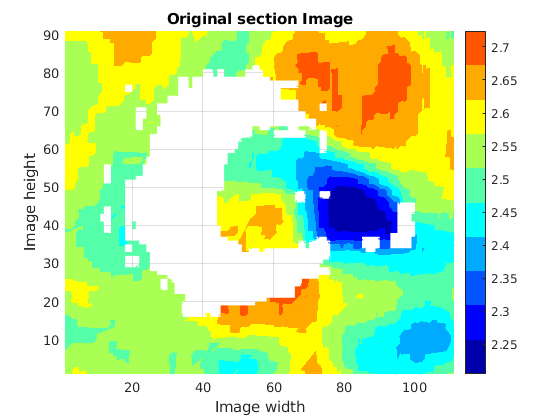

plotter(width_f,height_f,glare_tensor_f(:,:,1),title_,z_label,save_,0);


title_ = "Logestic Regression results";
z_label = "1: Valid, 0:Invalid"

z_label = "1: Valid, 0:Invalid"

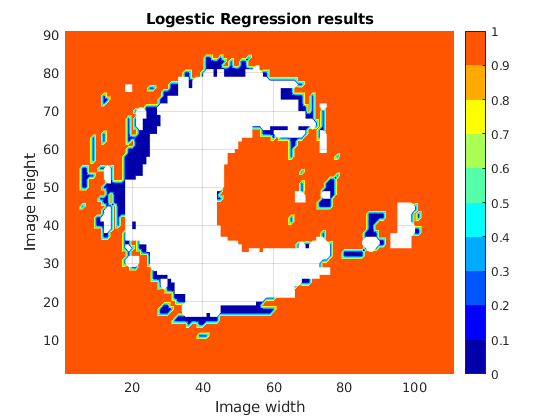

plotter(width_f,height_f,logestic_prob_mat,title_,z_label,save_,0);


title_ = "Z Score Matrix";
z_label = "Low Z score represent simillarity in the distribution"

z_label = "Low Z score represent simillarity in the distribution"

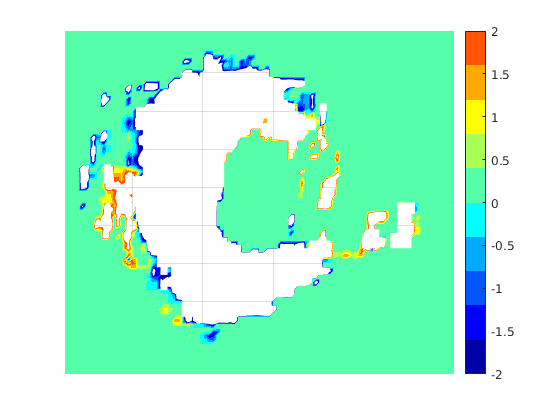

plotter(width_f,height_f,Z_score_matrix,title_,z_label,save_,2);


title_ = "Valid points in the image as per Zstatistics 95% confidence";
z_label = "Filtered Z Score";
% plotter(width_f,height_f,valid_zscore_matrix,title_,z_label,save_,0);

title_ = "Valid point based on the Z statistics binary";
z_label = "1-> point is valid | NaN -> point is invalid"

z_label = "1-> point is valid | NaN -> point is invalid"

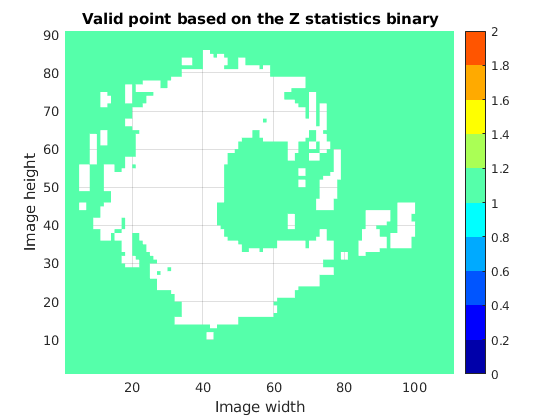

plotter(width_f,height_f,valid_zscore_matrix_binary,title_,z_label,save_,0);


title_ = "Valid points from the Logestic classifier";
z_label = "1-> point is valid | 0 -> point is invalid";
% plotter(width_f,height_f,logestic_prob_mat,title_,z_label,save_,0);

title_ = "Valid points from the Logestic classifier";
z_label = "1-> point is valid | NaN -> point is invalid"

z_label = "1-> point is valid | NaN -> point is invalid"

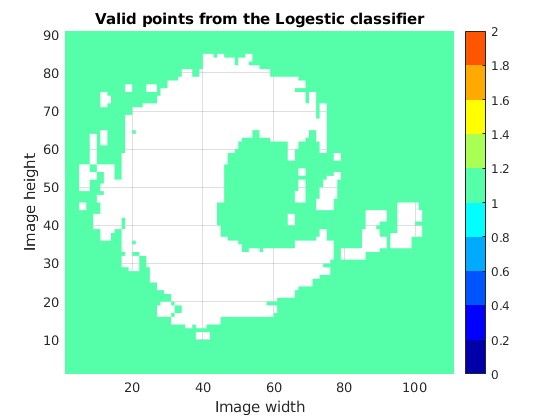

plotter(width_f,height_f,logestic_prob_mat_binary,title_,z_label,save_,0);


[rows, columns] = size(valid_zscore_matrix_binary);

type_1_mat = NaN(size(valid_zscore_matrix_binary));
type_2_mat = NaN(size(valid_zscore_matrix_binary));

for i=1:rows
    for j=1:columns
        if(valid_zscore_matrix_binary(i,j) ~= logestic_prob_mat_binary(i,j))
            if(valid_zscore_matrix_binary(i,j) == 1)
                type_1_mat(i,j) = 1;
            elseif (logestic_prob_mat_binary(i,j) == 1)
                type_2_mat(i,j) = 1;
            end

        end
    end
end

title_ = "Type 1: As per the Zstatistics the point is valid but Classifier clasify it as a Invalid";
z_label = "Type 1"

z_label = "Type 1"

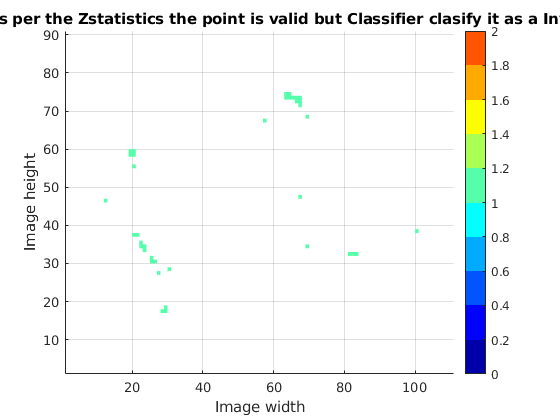

plotter(width_f,height_f,type_1_mat,title_,z_label,save_,0);


title_ = "Type 2: As per the Zstatistics the point is Invalid but Classifier clasify it as a Valid";
z_label = "Type 2"

z_label = "Type 2"

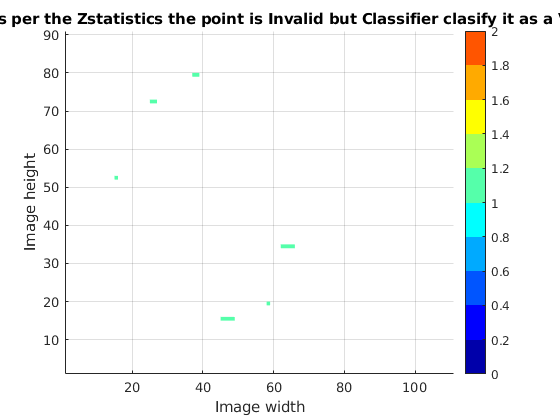

plotter(width_f,height_f,type_2_mat,title_,z_label,save_,0);


Total_points = width_f*width_f

Total_points = 12321


Valid_points_from_ZStatistics = sum(valid_zscore_matrix_binary(:) == 1)

Valid_points_from_ZStatistics = 7611

Invalid_points_from_ZStatistics = Total_points - Valid_points_from_ZStatistics

Invalid_points_from_ZStatistics = 4710


Valid_points_from_Classifier = sum(logestic_prob_mat_binary(:) == 1)

Valid_points_from_Classifier = 7489

Invalid_points_from_Classifier = Total_points - Valid_points_from_Classifier

Invalid_points_from_Classifier = 4832


Type_1_error_count = sum(type_1_mat(:) == 1)

Type_1_error_count = 212

Type_2_error_count = sum(type_2_mat(:) == 1)

Type_2_error_count = 90

function datasetgenerator(glare_tensor_f, Nan_zscore_matrix, valid_zscore_matrix)
tensor_size= size(glare_tensor_f);
no_of_call_backs = tensor_size(3);
width_f = tensor_size(2);
height_f = tensor_size(1);

count = 0;
count_valid = 0;

for i=1:5
    for j=6:width_f-5
        for k=6:height_f-5
            if(~(isnan(Nan_zscore_matrix(k,j))) & ~isinf(Nan_zscore_matrix(k,j)))
                if(~(isnan(glare_tensor_f(k,j,i))))
                    count = count+1;
                    distance = glare_tensor_f(k,j,i);
                    std_dev = nanstd(glare_tensor_f(k-2:k+2,j-2:j+2,i),1,'all');
                    no_of_nan   = sum(isnan(reshape(glare_tensor_f(k-2:k+2,j-2:j+2,i),[1,25])));
                    mat(count,:) = [distance, std_dev,no_of_nan, 0,j,k,i];
                end
            elseif(~(isnan(valid_zscore_matrix(k,j))))
                count_valid= count_valid+1;
                distance = glare_tensor_f(k,j,i);
                std_dev = nanstd(glare_tensor_f(k-2:k+2,j-2:j+2,i),1,'all');
                no_of_nan   = sum(isnan(reshape(glare_tensor_f(k-2:k+2,j-2:j+2,i),[1,25])));
                mat_valid(count_valid,:) = [distance, std_dev,no_of_nan, 1,j,k,i];
            end
        end
    end
    out = randperm(count_valid,count);
    for l = count+1:2*count
    mat(l,:) = mat_valid(out(l-count),:);
    end
    
    csvwrite('/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/datanew'+string(i)+'csv',mat)
    size(mat);
    mat =[];
    mat_valid =[];
    
end
end

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
function pointDistribution(point_vec,height,width,sample_count)
figure
height
width
no_of_nan = sum(isnan(point_vec))
if(no_of_nan<sample_count)
    histfit(point_vec,25,'normal')
else
    t = "all values Nan so distribution plot not possible"
end
end
function Z_score_matrix = classifyPoint(mean_map,stddev_map,no_of_nan_mat,wo_mean_map,wo_stddev_map,wo_no_of_nan_mat)

Z_score_matrix = zeros(size(mean_map));

difference_matrix = 1000*(wo_mean_map - mean_map);
sq_rt_no_of_nan_mat = no_of_nan_mat.^0.5;
intermediate_mat = (wo_mean_map - mean_map).*sq_rt_no_of_nan_mat;

Z_score_matrix = intermediate_mat./stddev_map;
max(Z_score_matrix);

end

function plotter(width,height,individual_callbacks,title_,z_label,save_,z_lim)
figure
if(z_lim == 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end
if(z_lim ~= 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    grid on
    view(2)
    zlim([-1*z_lim,z_lim]);
    caxis([-1*z_lim,z_lim]);
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end
end

